% Load MNIST Dataset (Use a custom loader for CIFAR-10)
digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', 'nndatasets', 'DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Resize Images to a Vector
inputSize = [28 28]; % MNIST image size
imds.ReadFcn = @(x) imresize(imread(x), inputSize);
[trainData, testData] = splitEachLabel(imds, 0.8);

% Prepare Training Data
trainImages = zeros(numel(trainData.Files), prod(inputSize));
for i = 1:numel(trainData.Files)
    img = readimage(trainData, i);
    trainImages(i, :) = double(img(:))' / 255; % Vectorize and normalize
end
trainLabels = trainData.Labels;

% Train the SVM
svmModel = fitcecoc(trainImages, trainLabels, 'Coding', 'onevsall', 'Learners', 'Linear');

% Prepare Testing Data
testImages = zeros(numel(testData.Files), prod(inputSize));
for i = 1:numel(testData.Files)
    img = readimage(testData, i);
    testImages(i, :) = double(img(:))' / 255;
end
testLabels = testData.Labels;

% Predict and Evaluate
predictedLabels = predict(svmModel, testImages);
accuracy = mean(predictedLabels == testLabels);

disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 40.8%


% Generate Confusion Matrix
confMat = confusionmat(testLabels, predictedLabels); % Numerical matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    56    38    33    28    18     6     1    16     3     1
     0   166     2    20     1     3     7     1     0     0
     1    36    85    38     5    12     3    17     0     3
     0    36    27   106     2     6     0     9     7     7
     0     6     0    12   151     5    16     2     8     0
     0    62     0    49    29    26    18     1    11     4
     0    94    30    18     8     1    33     0    16     0
     4    33    17     3     6     5     6   115     8     3
     0    63    24    74     6     1    21     3     2     6
     9    11    22    12    40    27     0     3     0    76



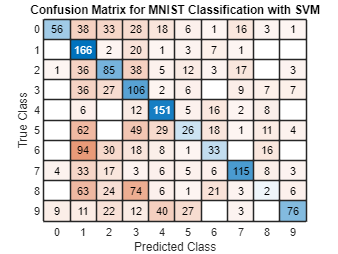


% Plot Confusion Matrix
figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for MNIST Classification with SVM');

% Specify the directory containing CIFAR-10 batches
dataDir = 'C:\Users\Yunus\Downloads\cifar-10-matlab\cifar-10-batches-mat';



% Load all training batches
trainImages = [];
trainLabels = [];
for batch = 1:5
    fileName = fullfile(dataDir, sprintf('data_batch_%d.mat', batch));
    [batchData, batchLabels] = loadBatch(fileName);
    trainImages = cat(4, trainImages, batchData);
    trainLabels = [trainLabels; batchLabels];
end

% Load test batch
[testImages, testLabels] = loadBatch(fullfile(dataDir, 'test_batch.mat'));

% Normalize pixel values to [0, 1]
trainImages = double(trainImages) / 255;
testImages = double(testImages) / 255;

disp('Data successfully loaded and preprocessed!');

Data successfully loaded and preprocessed!


% Function to load a single batch

% Flatten images for SVM
trainDataFlattened = reshape(trainImages, [], size(trainImages, 4))'; % [N x 3072]
testDataFlattened = reshape(testImages, [], size(testImages, 4))'; % [N x 3072]

% Train an SVM
svmModel = fitcecoc(trainDataFlattened, trainLabels, 'Coding', 'onevsall', 'Learners', 'Linear');

% Predict on the test set
predictedLabels = predict(svmModel, testDataFlattened);

% Generate confusion matrix
confMat = confusionmat(testLabels, predictedLabels);

% Display confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

     4     4     0     1   705     0    10    13   262     1
     1   107     2    10   655     0    23    14   160    28
     0     5    10     6   885     1    31    11    50     1
     0     4     4    16   860     1    52     7    53     3
     0     1     1     4   946     0    21     5    22     0
     2     2     6    11   860     4    40    12    61     2
     0     2     0     3   830     0   146     2    15     2
     0     1     2     6   850     0    20    90    30     1
     1     8     1     2   490     0     6     6   480     6
     1    20     1     5   669     3    42    38   147    74



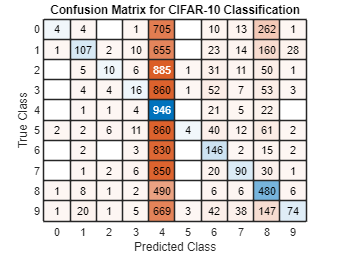


% Visualize confusion matrix
figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for CIFAR-10 Classification');

% Predict and Evaluate


accuracy = mean(predictedLabels == testLabels);

disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 18.77%


function [data, labels] = loadBatch(filePath)
    batch = load(filePath);
    data = reshape(batch.data, [], 32, 32, 3); % Reshape to 32x32x3
    data = permute(data, [2, 3, 4, 1]); % Rearrange dimensions to [32x32x3xN]
    labels = categorical(batch.labels); % Convert labels to categorical
end